# Servomecanismos Proyecto Académico

*Isa y los Servotasticos*

clc
clear

## Constantes

Se fijan los valores de a y b para que el trébol mida 15 cm de lado y esté sin rotar (esto se usa más adelante, en el modelo del trébol):

a_min = 1.332; % No cambiar 1.332
b_no_rot = 4.71; % No cambiar 4.71
g = 981; % gravedad en cm/s^2

## Config

### Centros

punto_fijo = [0; 0];
centro_trebol = [25; 25];

#### Largo de eslabones 

Con esto, necesitamos que los eslabones en máxima extensión midan al menos:

lado_trebol_max = 15*1.33;
diagonal_max = hypot(lado_trebol_max, lado_trebol_max);
radio_punto_max = hypot(centro_trebol(1), centro_trebol(2)) + diagonal_max/2

radio_punto_max = 49.4621

Se escogen como primera aproximación para la longitud de los eslabones:

largo_eslabon_1 = 20;
largo_eslabon_2 = 30;

El punto máximo al que llegarán estos eslabones es:

radio_alcance_max = largo_eslabon_1+largo_eslabon_2;

Con esto, es posible llegar a todos los puntos de la trayectoria con las longitudes escogidas para los eslabones. Y se deja una tolerancia de [cm]:

radio_tolerancia = radio_alcance_max - radio_punto_max

radio_tolerancia = 0.5379

#### Escala y rotación

escala = 1; % default = 1
rotacion = 3; % default = 0

### Número de puntos

puntos = 100;

### Masas

masa_eslabon_1 = 1;
masa_eslabon_2 = 1;

## Forward Kinematics

l1 = Link('revolute', 'd', 0, 'a', largo_eslabon_1, 'alpha', 0);
l2 = Link('revolute', 'd', 0, 'a', largo_eslabon_2, 'alpha', 0);
robot = SerialLink([l1 l2])

 
robot = 
 
noname:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|         20|          0|          0|
|  2|         q2|          0|         30|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Inverse Kinematics

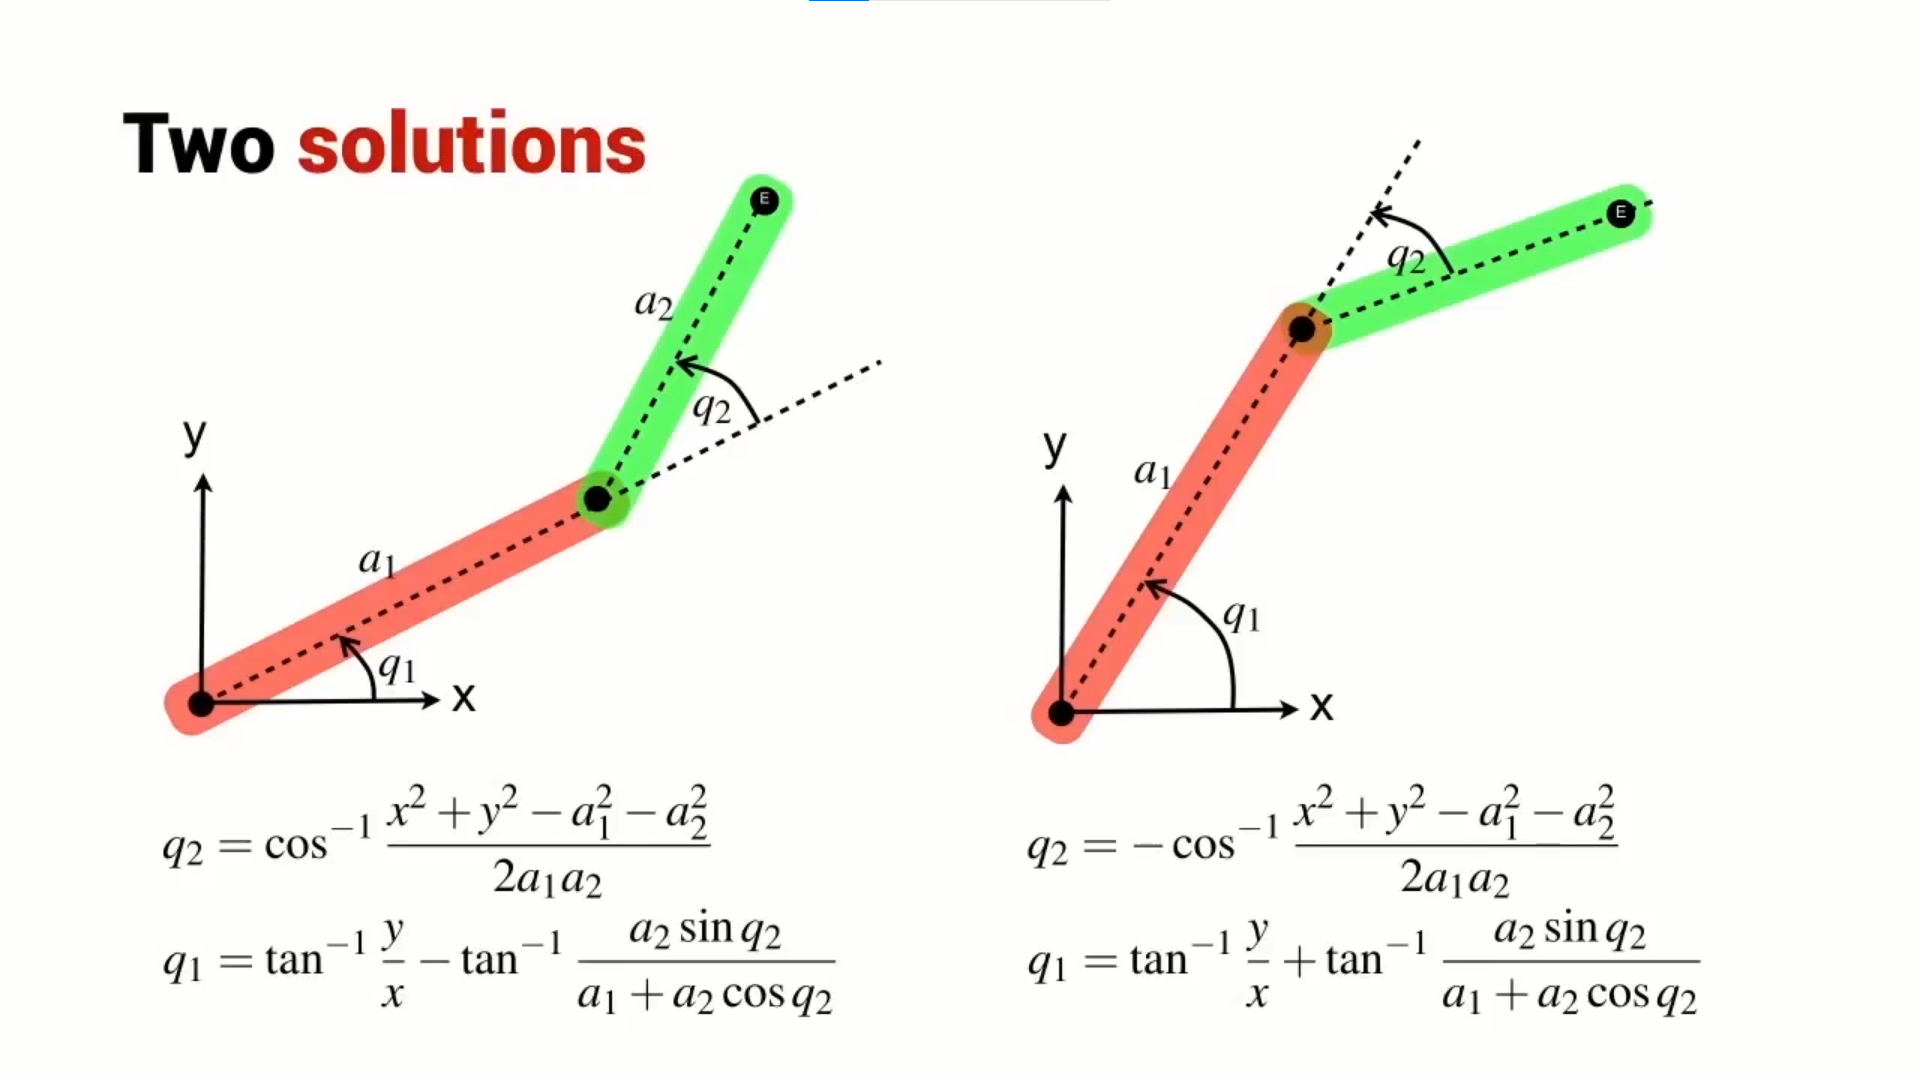

## Trébol

### Definir la trayectoria

syms theta_trebol;
a_trebol = a_min * escala;
b_trebol = b_no_rot + rotacion;
trebol_x(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*cos(theta_trebol)+centro_trebol(1);
trebol_y(theta_trebol) = (a_trebol*(sin(4*theta_trebol+b_trebol)+6)).*sin(theta_trebol)+centro_trebol(2);

### Discretización de la trayectoria

Si se quiere tener una mejor resolución en la discretización hay que cambiar la variable `intervalo_theta_trebol`. Entre más pequeño el intervalo mejor resolución.

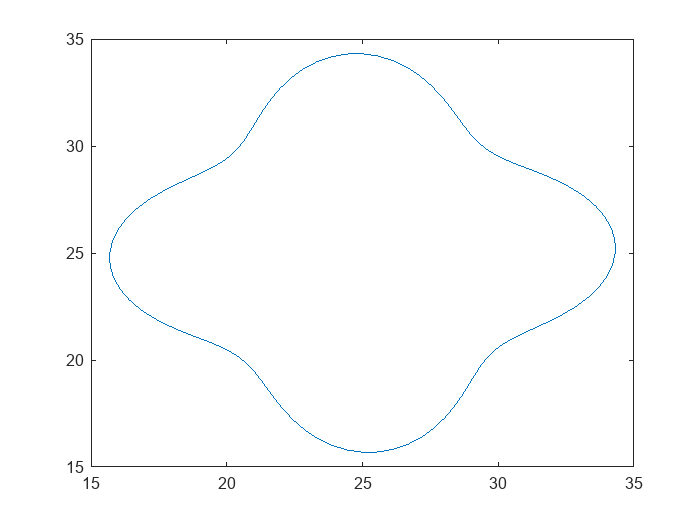

intervalo_theta_trebol = (2*pi)/(puntos);
theta_trebol_discreto = 0:intervalo_theta_trebol:2*pi;
trebol_discretizado_x = trebol_x(theta_trebol_discreto);
trebol_discretizado_y = trebol_y(theta_trebol_discreto);
plot(trebol_discretizado_x, trebol_discretizado_y);

### Cálculo del perímetro

perimetro = 0;
for i = 1:length(trebol_discretizado_x)-1
    % distancia entre puntos consecutivos
    dx = trebol_discretizado_x(i+1) - trebol_discretizado_x(i);
    dy = trebol_discretizado_y(i+1) - trebol_discretizado_y(i);
    distancia = sqrt(dx^2 + dy^2);
    % acumula
    perimetro = perimetro + distancia;
end
perimetro = eval(perimetro)

perimetro = 55.3905

tiempo_recorrido = perimetro/10

tiempo_recorrido = 5.5391

vector_tiempo = linspace(0,tiempo_recorrido,puntos+1)

vector_tiempo =          0    0.0554    0.1108    0.1662    0.2216    0.2770    0.3323    0.3877    0.4431    0.4985    0.5539    0.6093    0.6647    0.7201    0.7755    0.8309    0.8862    0.9416    0.9970    1.0524    1.1078    1.1632    1.2186    1.2740    1.3294    1.3848    1.4402    1.4955    1.5509    1.6063    1.6617    1.7171    1.7725    1.8279    1.8833    1.9387    1.9941    2.0494    2.1048    2.1602    2.2156    2.2710    2.3264    2.3818    2.4372    2.4926    2.5480    2.6034    2.6587    2.7141


## Ángulos para el recorrido

El último ángulo es igual al primero, por eso salen n+1 ángulos para n puntos.

[q1vec, q2vec] = get_angs_multi(largo_eslabon_1, largo_eslabon_2, trebol_discretizado_x, trebol_discretizado_y)

q1vec =     1.3266    1.3209    1.3211    1.3273    1.3389    1.3552    1.3749    1.3969    1.4197    1.4420    1.4628    1.4811    1.4966    1.5089    1.5182    1.5251    1.5300    1.5340    1.5380    1.5429    1.5500    1.5599    1.5735    1.5910    1.6126    1.6380    1.6664    1.6970    1.7286    1.7603    1.7910    1.8200    1.8466    1.8707    1.8925    1.9123    1.9308    1.9488    1.9672    1.9867    2.0080    2.0313    2.0569    2.0844    2.1135    2.1431    2.1725    2.2002    2.2251    2.2459


q2vec =    -1.1390   -1.1125   -1.0932   -1.0817   -1.0780   -1.0812   -1.0903   -1.1034   -1.1188   -1.1346   -1.1492   -1.1611   -1.1692   -1.1728   -1.1718   -1.1663   -1.1571   -1.1451   -1.1319   -1.1191   -1.1084   -1.1017   -1.1005   -1.1060   -1.1188   -1.1390   -1.1661   -1.1991   -1.2367   -1.2771   -1.3189   -1.3606   -1.4009   -1.4389   -1.4741   -1.5063   -1.5356   -1.5625   -1.5878   -1.6122   -1.6366   -1.6617   -1.6882   -1.7162   -1.7461   -1.7775   -1.8101   -1.8432   -1.8759   -1.9073


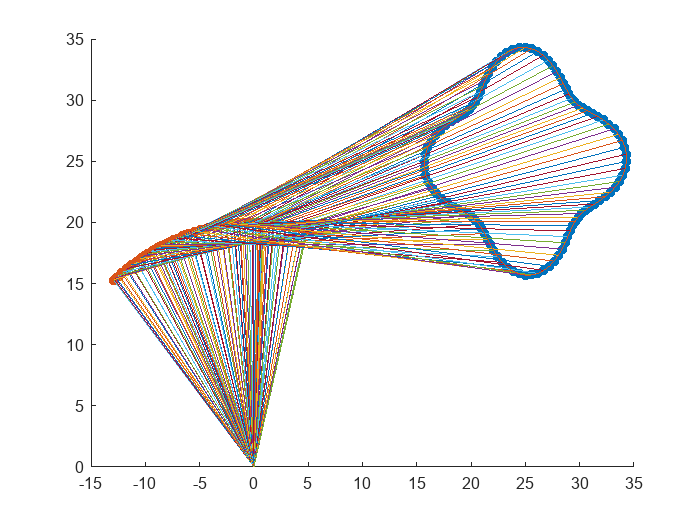

plot_all(trebol_discretizado_x, trebol_discretizado_y, q1vec, q2vec, robot, l1)

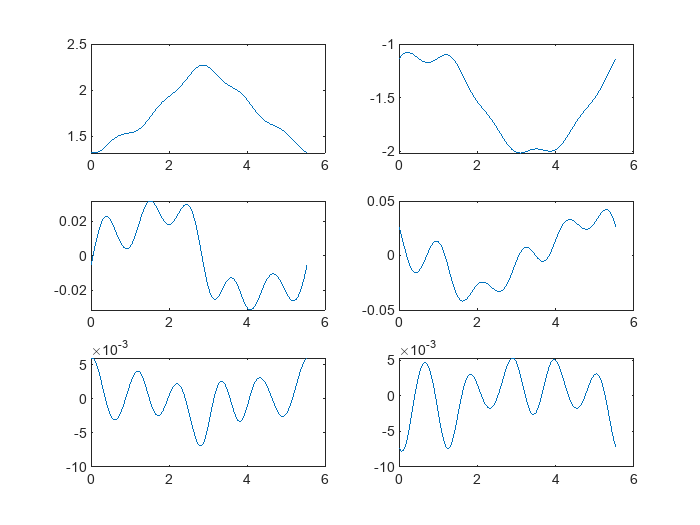

q1vecP = diff(q1vec);
q1vecP(end+1) = q1vecP(1);
q2vecP = diff(q2vec);
q2vecP(end+1) = q2vecP(1);
q1vecPP = diff(q1vecP);
q1vecPP(end+1) = q1vecPP(1);
q2vecPP = diff(q2vecP);
q2vecPP(end+1) = q2vecPP(1);

subplot(3,2,1)
plot(vector_tiempo,q1vec)
subplot(3,2,2)
plot(vector_tiempo,q2vec)
subplot(3,2,3)
plot(vector_tiempo,q1vecP)
subplot(3,2,4)
plot(vector_tiempo,q2vecP)
subplot(3,2,5)
plot(vector_tiempo,q1vecPP)
subplot(3,2,6)
plot(vector_tiempo,q2vecPP)

## Lagrange

vector_torques_q1 = [];
vector_torques_q2 = [];
m1 = masa_eslabon_1;
m2 = masa_eslabon_2;

l1 = largo_eslabon_1;
l2 = largo_eslabon_2;
for i = 1:length(vector_tiempo)-1
    theta1 = q1vec(i);
    theta2 = q2vec(i);
    theta1P = q1vecP(i);
    theta2P = q2vecP(i);
    theta1PP = q1vecPP(i);
    theta2PP = q2vecPP(i);
    
    % estos 4 deberían estar parametrizados
    lc1 = l1/2;
    lc2 = l2/2;
    Iz1 = 1;
    Iz2 = 1;
    
    c1 = cos(theta1);
    c2 = cos(theta2);
    s1 = sin(theta1);
    s2 = sin(theta2);
    c12 = cos(theta1+theta2);
    
    
    M_11 = m1*lc1^2 + Iz1 + m2*l1^2 + m2*lc2^2 + Iz2 + 2*m2*l1*lc2*c2;
    M_12 = m2*lc2^2 + Iz2 + m2*l1*lc2*c2;
    M_21 = m2*lc2^2 + m2*l1*lc2*c2 + Iz2;
    M_22 = m2*lc2^2 + Iz2;
    M = [M_11, M_12;
         M_21, M_22];
    
    thetaPP = [theta1PP;
                theta2PP];
    
    D = 2*m2*l1*lc2*s2*theta1P*theta2P;
    E = 2*m2*l1*lc2*s2*theta2P^2;
    N = -m2*l1*lc2*s2*theta1P*theta2P;
    
    C = [D.*theta1P.*theta2P + E.*theta2P^2;
         N.*theta1P.*theta2P-(-m2*l1*lc2*s2.*theta1P.*(theta1P+theta2P))];
    
    G = g.*[(m1*lc1+m2*l1)*c1 + m2*lc2*c12;
             m2*lc2*c12];
    
    torque = M*thetaPP + C + G;
    vector_torques_q1(end+1) = torque(1);
    vector_torques_q2(end+1) = torque(2);
end
vector_torques = [vector_torques_q1; vector_torques_q2]

vector_torques = 1.0e+04 *

    2.1577    2.1679    2.1610    2.1372    2.0982    2.0464    1.9851    1.9177    1.8483    1.7804    1.7169    1.6602    1.6115    1.5712    1.5386    1.5124    1.4904    1.4700    1.4486    1.4234    1.3918    1.3519    1.3022    1.2423    1.1727    1.0946    1.0102    0.9225    0.8342    0.7484    0.6674    0.5930    0.5262    0.4668    0.4141    0.3663    0.3214    0.2770    0.2307    0.1806    0.1254    0.0643   -0.0022   -0.0732   -0.1466   -0.2198   -0.2900   -0.3540   -0.4088   -0.4516
    1.4457    1.4397    1.4335    1.4274    1.4217    1.4166    1.4123    1.4085    1.4054    1.4025    1.3997    1.3968    1.3933    1.3892    1.3841    1.3778    1.3704    1.3617    1.3519    1.3413    1.3304    1.3197    1.3099    1.3017    1.2956    1.2920    1.2911    1.2928    1.2969    1.3030    1.3105    1.3189    1.3277    1.3364    1.3446    1.3519    1.3581    1.3631    1.3669    1.3696    1.3712    1.3721    1.3726    1.3728    1.3733    1.3742    1.3759 

## Funciones

Esta función se usa para plotear el brazo.

Esta función se usa para plotear el brazo y el trébol. Se pueden comentar algunas líneas dependiendo de la información que se busca.

function plot_all(trebol_x, trebol_y, q1vec, q2vec, robot, l1)
    % tool
    tx = [];
    ty = [];
    for i = 1:length(q1vec)
        onemth = robot.fkine([q1vec(i) q2vec(i)]);
        tx(end+1) = onemth.t(1);
        ty(end+1) = onemth.t(2);
    end
    scatter(tx, ty, 'filled');
    hold on
    % codo
    cx = [];
    cy = [];
    for i = 1:length(q1vec)
        onemth = l1.A([q1vec(i)]);
        cx(end+1) = onemth.t(1);
        cy(end+1) = onemth.t(2);
    end
    scatter(cx, cy, 'filled');
    % linea del origen al codo
    for i = 1:length(cx)
        plot([cx(i), 0], [cy(i), 0]);
    end
    % linea del codo al tool
    for i = 1:length(cx)
        plot([cx(i), tx(i)], [cy(i), ty(i)]);
    end
    % trebol
    plot(trebol_x, trebol_y);
    hold off
end

Cinematica inversa

function [q1, q2] = get_angs(a1, a2, x, y)
    q2 = [acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2)); -acos((x^2+y^2-a1^2-a2^2)/(2*a1*a2))];
    q1 = [atan2(y,x)-atan2((a2*sin(q2)),(a1+a2*cos(q2))); atan2(y,x)+atan2((a2*sin(q2)),(a1+a2*cos(q2)))];
    q1 = q1(1:2);
end

Multi inversa

function [q1vec, q2vec] = get_angs_multi(a1, a2, x, y)
    q1vec = [];
    q2vec = [];
    for i = 1:length(x)
        [q1, q2] = get_angs(a1, a2, x(i), y(i));
        q1vec(end+1) = q1(2); % una de las respuestas se está ignorando
        q2vec(end+1) = q2(2);
    end
end